M = [3 -2;2 -2];
f = @(t,yz) M*yz

f = function_handle with value:
    @(t,yz)M*yz


f = function handle with value;

    @(t, yz)M*yz

yz0 = [1;-1]

yz0 =      1
    -1


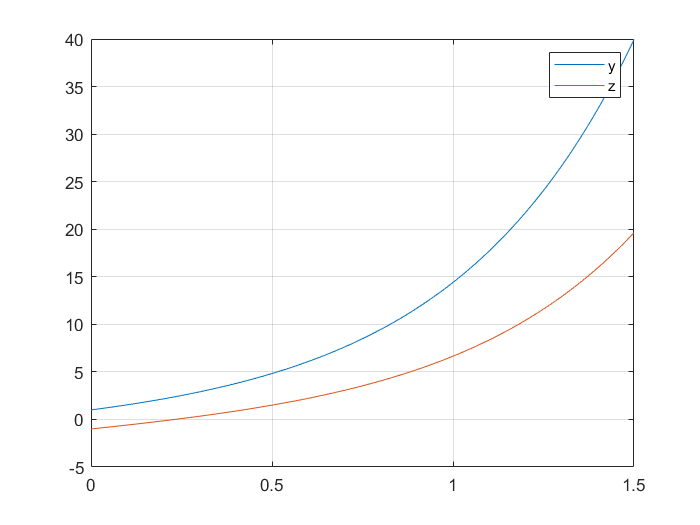

[t, yz] = ivps(f,0,1.5,yz0,.01,4);
plot(t,yz)
grid on;
legend('y','z');

Esto es lo mismo que hacer lo de abajo (que es lo que hemos hecho hasta el momento) pero usando una matriz para no escribir todo.

f = @(t,yz) [3*yz(1) - 2*yz(2); 2*yz(1) - 2*yz(2)];
yz0 = [1;-1];
[t, yz] = ivps(f,0,1.5,yz0,.01,4);
plot(t,yz)
grid on;
legend('y','z');

[V,D] = eig(M)

V =     0.8944    0.4472
    0.4472    0.8944


D =      2     0
     0    -1


c = V\yz0

c =     2.2361
   -2.2361
